## Gain Scheduling

Il gain scheduling è una tecnica di controllo complementare alla feedback linearization. L'approccio consiste nel progettare tanti piccoli controllori ottimi nei punti di equilibrio e successivamente usiamo questi controllori per l'interpolazione. Abbiamo a disposizione un impianto non lineare, il riferimento e l'uscita e inseriamo una variabile di errore avendo a disposizione n-controllori. Ogni controllore può essere agganciato all'impianto, ma solo uno si aggancia al controllore vero. Ciò che seleziona il controllore in base alle condizioni operative è lo scheduler che determina la posizione su cui muovere il selettore. Il vantaggio rispetto alla feedback linearization è che il controllore è costruito per tenere conto di incertezze ed altri parametri incerti che variano nel tempo. $\sigma$ è la variabile di scheduling la cui scelta dipende dal progettista.

 Vi sono 5 passi fondamentali per applicare tale tecnica: 

- Identificazione delle condizioni operative: $\sigma
$

- Linearizzazione intorno ai trim points

- Scelta di una famiglia di controllori locali

- Interpolazione di $k (\sigma)$

- Valiazione numerica

## Step 1: individuazione dei trim points

**Assunzione: ***esiste una famiglia di punti di equilibrio parametrizzabile in *$\sigma$*.*

### Parametro di scheduling


$$r=\sigma 

$$


### Sistema non lineare 


$$\begin{cases}
\dot x_1 =x_2 \\
\dot{x_2} =- \frac{g}{l} sin x_1- \frac{b}{ml^2}x_2+ \frac{u(t)}{ml^2}\\
y=x_1
\end{cases}$$


dove $y=x_1 =\sigma \;$e $u=\textrm{Kx}+{\;K}_r r$ con $x={\left\lbrack x_1 \;x_2 \right\rbrack }^{\prime } \;;K={\left\lbrack K_1 \;K_2 \right\rbrack }^{\prime }$

dove sostituendo i valori dei parametri otteniamo:


$$\begin{cases}
\dot x_1 =x_2
\\
\dot{x_2} =-9.81sin x_1- \frac{1}{10}x2+ u(t)\\
u(t)=-K_1 x_1-K_2x_2+K_r\sigma 
\end{cases} $$


clear, close all, clc;
mkdir ('Risultati_Gain')

mkdir ('Risultati_Gain_LookUpTable')

m = 1; 
l = 1;
b = 0.1;
g = 9.81;
syms u x1 x2 sigma y; 
r=pi

r = 3.1416

x1_dot = x2

$$x1\_dot = x_{2}$$

x2_dot = (g/l)*sin(x1) - (b/(m*l^2)*x2) + (u/(m*l^2))

$$x2\_dot = u-\frac{x_{2}}{10}+\frac{981\,\sin\left(x_{1}\right)}{100}$$

y=x1

$$y = x_{1}$$

### Calcolo dei punti di equilibrio

% Imposta le equazioni di stato a zero per trovare i punti di equilibrio
equazioni = [x1_dot == 0, x2_dot == 0,y == sigma];
risolutori= [u,x1,x2]

$$risolutori = \left(\begin{array}{ccc} u & x_{1} & x_{2} \end{array}\right)$$

sols = solve(equazioni, risolutori) 

sols = struct with fields:
     u: -(981*sin(sigma))/100
    x1: sigma
    x2: 0



x_1_e = sols.x1

$$x\_1\_e = \sigma$$

x_2_e = sols.x2 

$$x\_2\_e = 0$$

u_e = sols.u

$$u\_e = -\frac{981\,\sin\left(\sigma \right)}{100}$$

## Step 2: linearizzazione attorno ai trim points

Esplicitando la $u$ si ottiene:


$$\begin{cases}
\dot x_1 =x_2 \\
\dot{x_2} = 9.81sin x_1- \frac{1}{10}x_2+-K_1 x_1-K_2x_2\\
y= x_1
\end{cases}$$


syms K1 K2 Kr;
x1_dot = x2

$$x1\_dot = x_{2}$$

x2_dot = (g/l)*sin(x1) - ((b*x2)/(m*l^2)) + (-K1*x1-K2*x2)/(m*l^2) 

$$x2\_dot = \frac{981\,\sin\left(x_{1}\right)}{100}-\frac{x_{2}}{10}-K_{1}\,x_{1}-K_{2}\,x_{2}$$

y=x1

$$y = x_{1}$$

Linearizzazione attorno ai trim points

J_a = jacobian([x1_dot,x2_dot],[x1,x2]);
J_b = jacobian([x1_dot,x2_dot],sigma);

A = subs(J_a, {'x1', 'x2'}, [x_1_e, x_2_e])

$$A = \left(\begin{array}{cc} 0 & 1\\ \frac{981\,\cos\left(\sigma \right)}{100}-K_{1} & -K_{2}-\frac{1}{10} \end{array}\right)$$

B = subs(J_b, 'u', u_e)

$$B = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

## Step 3: sintesi locale del controllore

### Calcolo del polinomio caratteristico

Per il calcolo del polinomio caratteristico useremo charpoly.

**Metodo charpoly**

pol = charpoly(A) 

$$pol = \left(\begin{array}{ccc} 1 & K_{2}+\frac{1}{10} & K_{1}-\frac{981\,\cos\left(\sigma \right)}{100} \end{array}\right)$$

### Stabilità

La stabilità si ottiene imponendo che non ci siano permutazioni di segno nei coefficienti del polinomio caratteristico:

                                                                                                            
$$\begin{cases}
        K_1\ -9.81cos(\sigma)>0\\
       K_2+\frac{1}{10}> 0
\end{cases}
    =
    \begin{cases}
        K_1 > 9.81cos(\sigma)\\
        K_2 > -\frac{1}{10}
    \end{cases}$$


Polinomio caratteristico: 

### Specifiche dinamiche

Se si vogliono imporre altre specifiche oltre la stabilità si possono utilizzare il coefficiente di smorzamento $\zeta$ e la pulsazione $\omega_0$. Di fatti il polinomio caratteristico di un sistema del secondo ordine è del tipo:


$$ \lambda^2 + 2\zeta\omega_0\lambda +  \omega_0^2= 0$$



$$\begin{cases}
2\zeta\omega_0=K_2+\frac{1}{10}\\ 
\omega_0^2=K_1 -9.81cos(\sigma)\\
\end{cases}$$


Per evitare oscillazioni del sistema linearizzato dobbiamo imporre radici reali. Notiamo che con questo evitiamo le oscilllazioni soltanto del sistema linearizzato e non di quello a ciclo chiuso. 

Imponendo a ciclo chiuso un tempo di salita pari a $T_r =0\ldotp 4s$, si ottiene:


$$T_r =\frac{2\ldotp 7}{\omega_0 }\leftrightarrow \omega_0 =\frac{2\ldotp 7}{T_r }=6\ldotp 75$$


Per avere un comportamento privo di sovraelongazione(seguendo ragionamenti analoghi alla FBL) si impone:


$$\zeta =0\ldotp 9$$


Il polinomio caratteristico desiderato sarà quindi nella forma:


$$p\left(s\right)=s^2 +2\zeta \omega_0 s+\omega_0^2 =s^2 +12\ldotp 15s+45\ldotp 5625$$


Tr=0.4

Tr = 0.4000

w0 = 2.7/Tr

w0 = 6.7500

zeta = 0.9

zeta = 0.9000


pol_d = [1 2*zeta*w0 w0^2]

pol_d =     1.0000   12.1500   45.5625


Per il principio di equivalenza dei polinomi si ottiene:


$$\begin{cases}
K_2=2\zeta\omega_0-\frac{1}{10}\\ 
K_1=\omega_0^2+9.81cos(\sigma) \\
\end{cases}$$


gains = solve(pol == pol_d, [K2, K1])

gains = struct with fields:
    K2: 241/20
    K1: (981*cos(sigma))/100 + 729/16


K1=gains.K1

$$K1 = \frac{981\,\cos\left(\sigma \right)}{100}+\frac{729}{16}$$

K2=gains.K2 

$$K2 = \frac{241}{20}$$

 
$$\begin{cases}
        K_1 =45.5625+9.81cos(\sigma)\\
        K_2 =12.05
 \end{cases}$$


### Progettazione dei controllori per ciascun trim point

Assumendo che il riferimento del sistema può variare in un range da $\left\lbrack 0,\pi \;\right\rbrack$, si progettano i controllori al variare della variabile di scheduling $\sigma$:

% Range di valori per sigma
sigma_values = 0:00.1:2*pi;

% Inizializzazione degli array per i guadagni
K1_sigma = [];
K2_sigma = [];
% Calcolo dei guadagni per ogni valore di sigma
for sigma = sigma_values
    % Calcola K1, K2, Kr per il valore corrente di sigma
    K1 = double(subs(K1, 'sigma', sigma));
    K2 = double(subs(K2, 'sigma', sigma));
    % Aggiungi i guadagni calcolati agli array
    K1_sigma = [K1_sigma, K1];
    K2_sigma = [K2_sigma, K2];
end

% Visualizza i valori dei guadagni
K1_sigma;
K2_sigma;
%K_sigma=[K1_sigma K2_sigma]
vpa(K1_sigma);
vpa(K2_sigma);

## Simulation

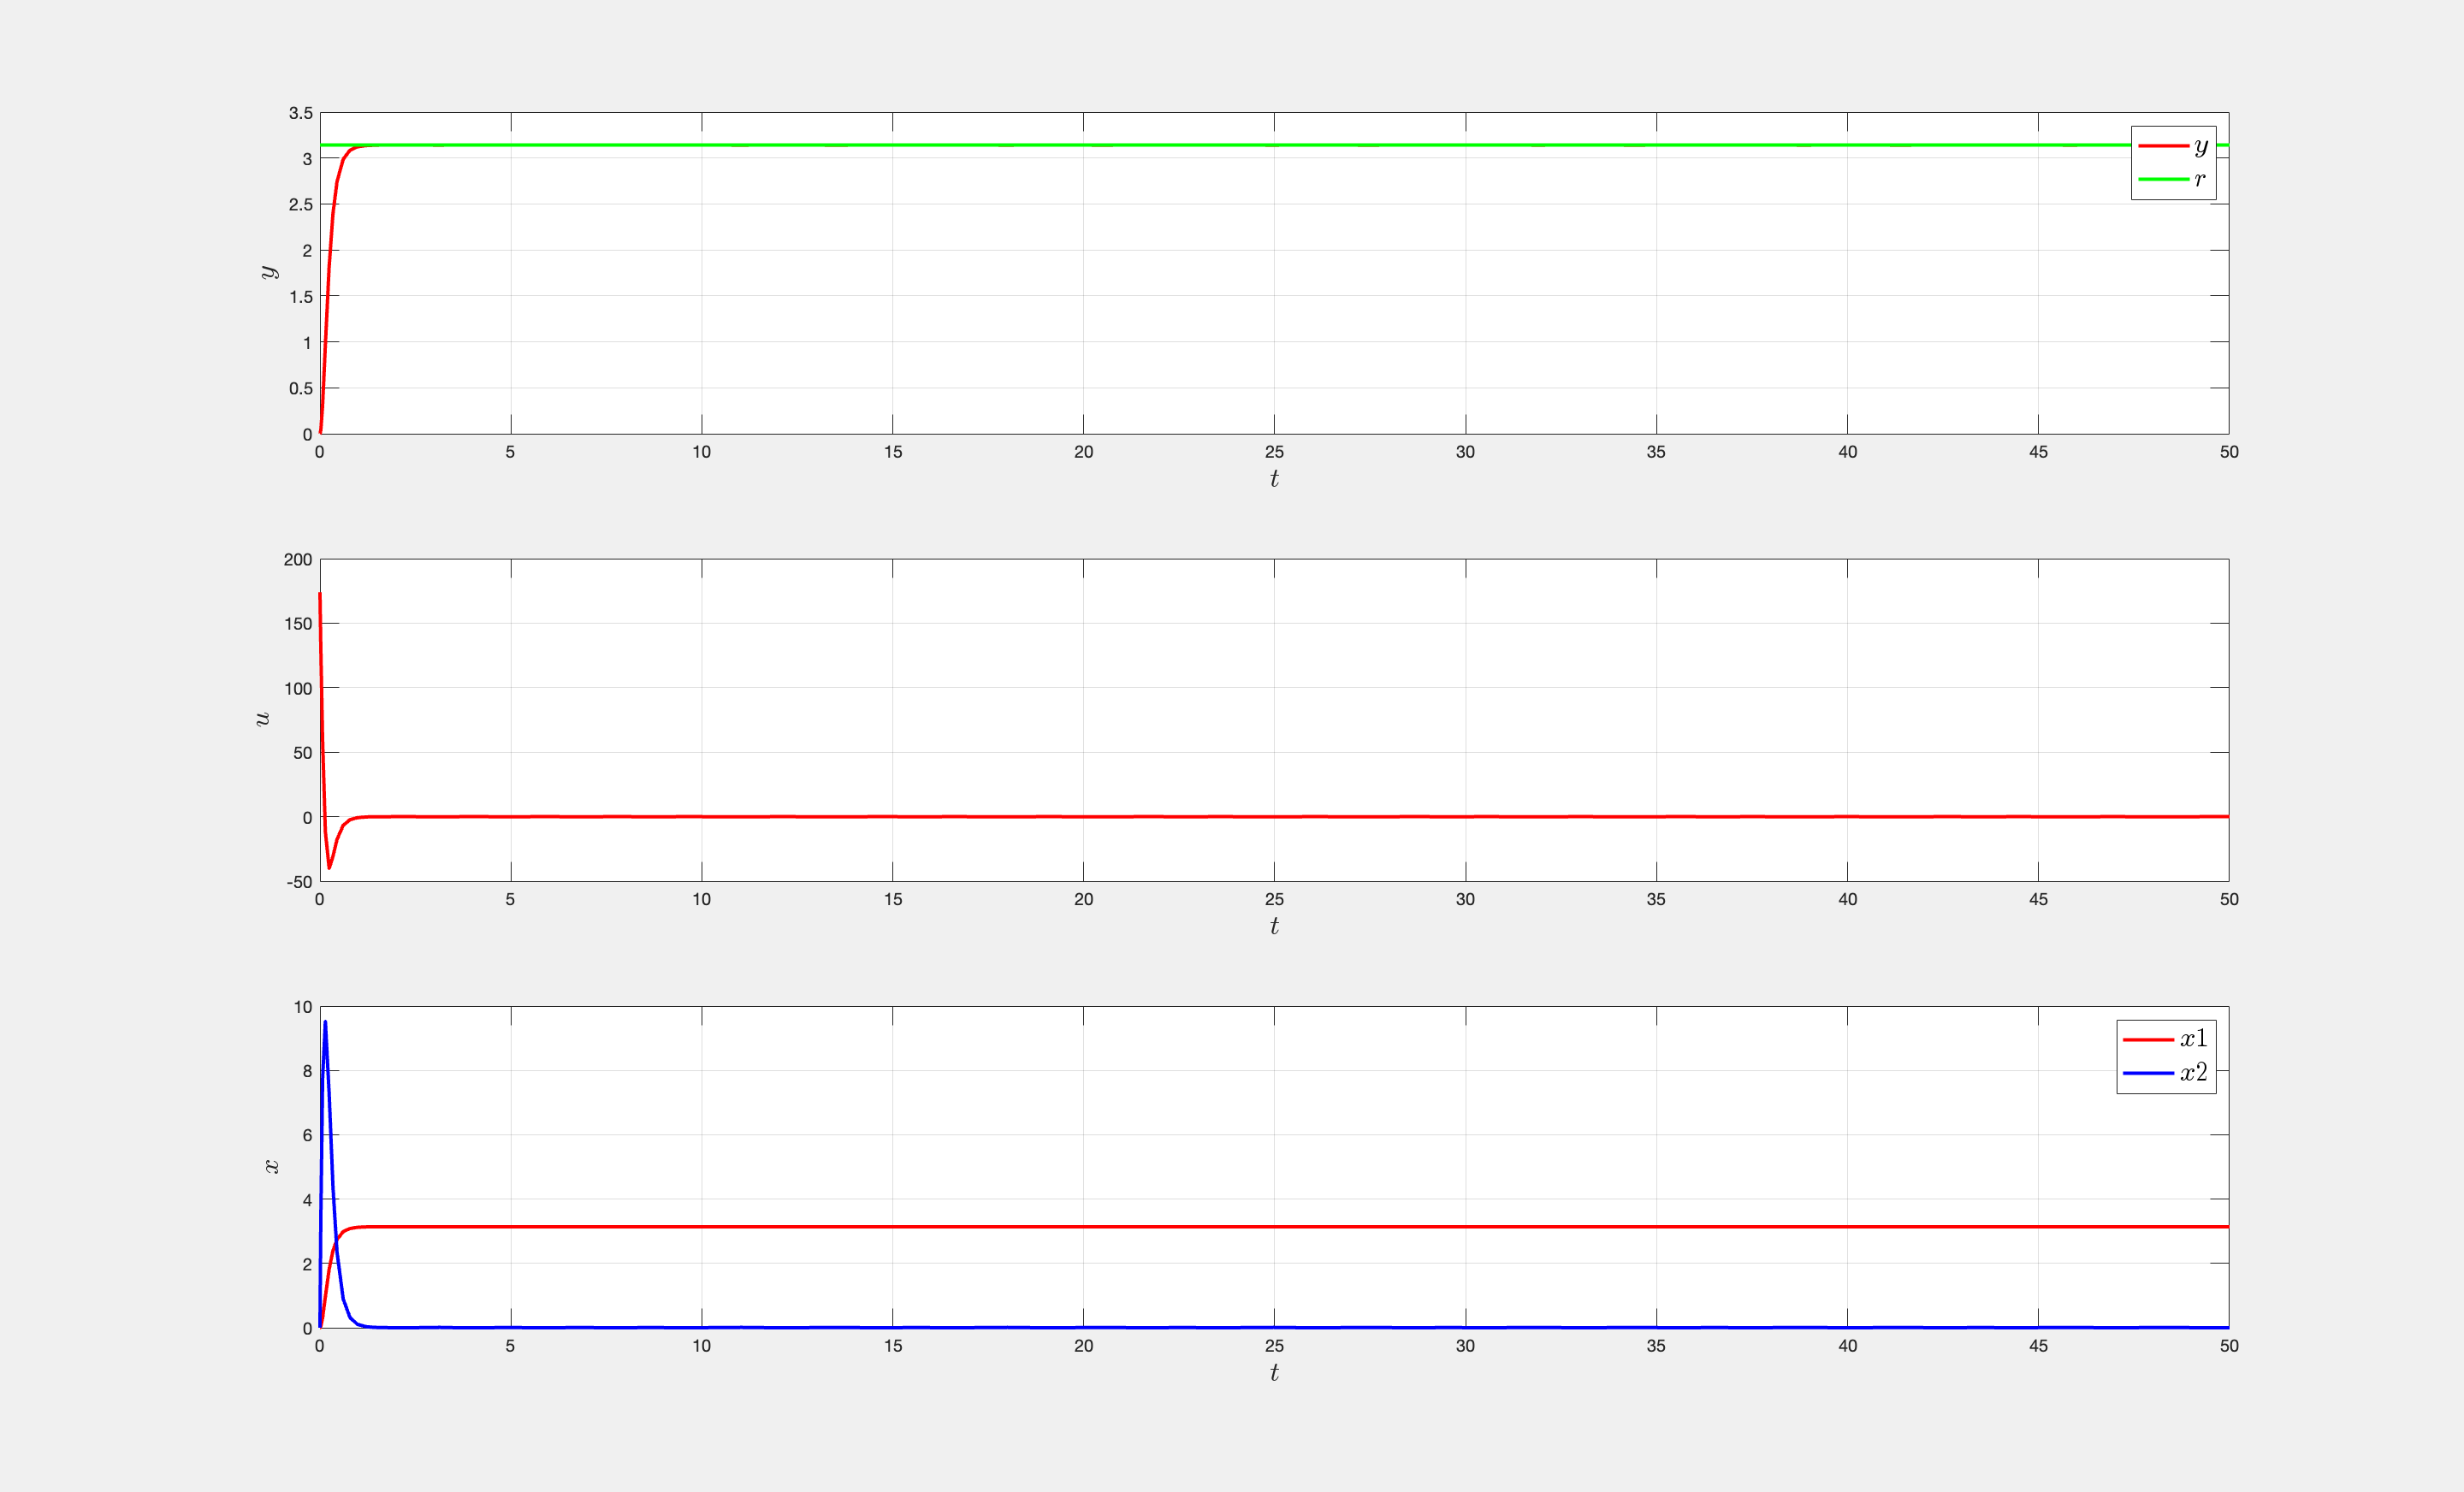

standard_model = 'GainSchedulingSimulink.slx';
open_system(standard_model);
data = sim(standard_model, 50);
%plot_data(data, "GainSchedulingSimulink");
%saveas(gcf,'Risultati_Gain/Results.png');
% Genera un timestamp unico per includere nella stringa del nome del file
timestamp = datestr(now, 'yyyymmdd_HHMMSS');

% Crea una stringa univoca per il nome del file
imageName = ['Results_', timestamp, '.png'];

% Plot dei dati
plot_data(data, "GainSchedulingSimulink");

% Salva l'immagine con un nome univoco
saveas(gcf, fullfile('Risultati_Gain', imageName))

#### Analisi

y = squeeze(data.y.Data); % Ridimensiona y per rimuovere le dimensioni singolari
t = squeeze(data.t.Data); % Ridimensiona y per rimuovere le dimensioni singolari
results=stepinfo(y,t);
disp('Step Information for the Output');

Step Information for the Output


disp(results);

         RiseTime: 0.4332
    TransientTime: 0.7738
     SettlingTime: 0.7738
      SettlingMin: 2.9864
      SettlingMax: 3.1415
        Overshoot: 2.5742e-04
       Undershoot: 0
             Peak: 3.1415
         PeakTime: 3.8516



#### Look up table

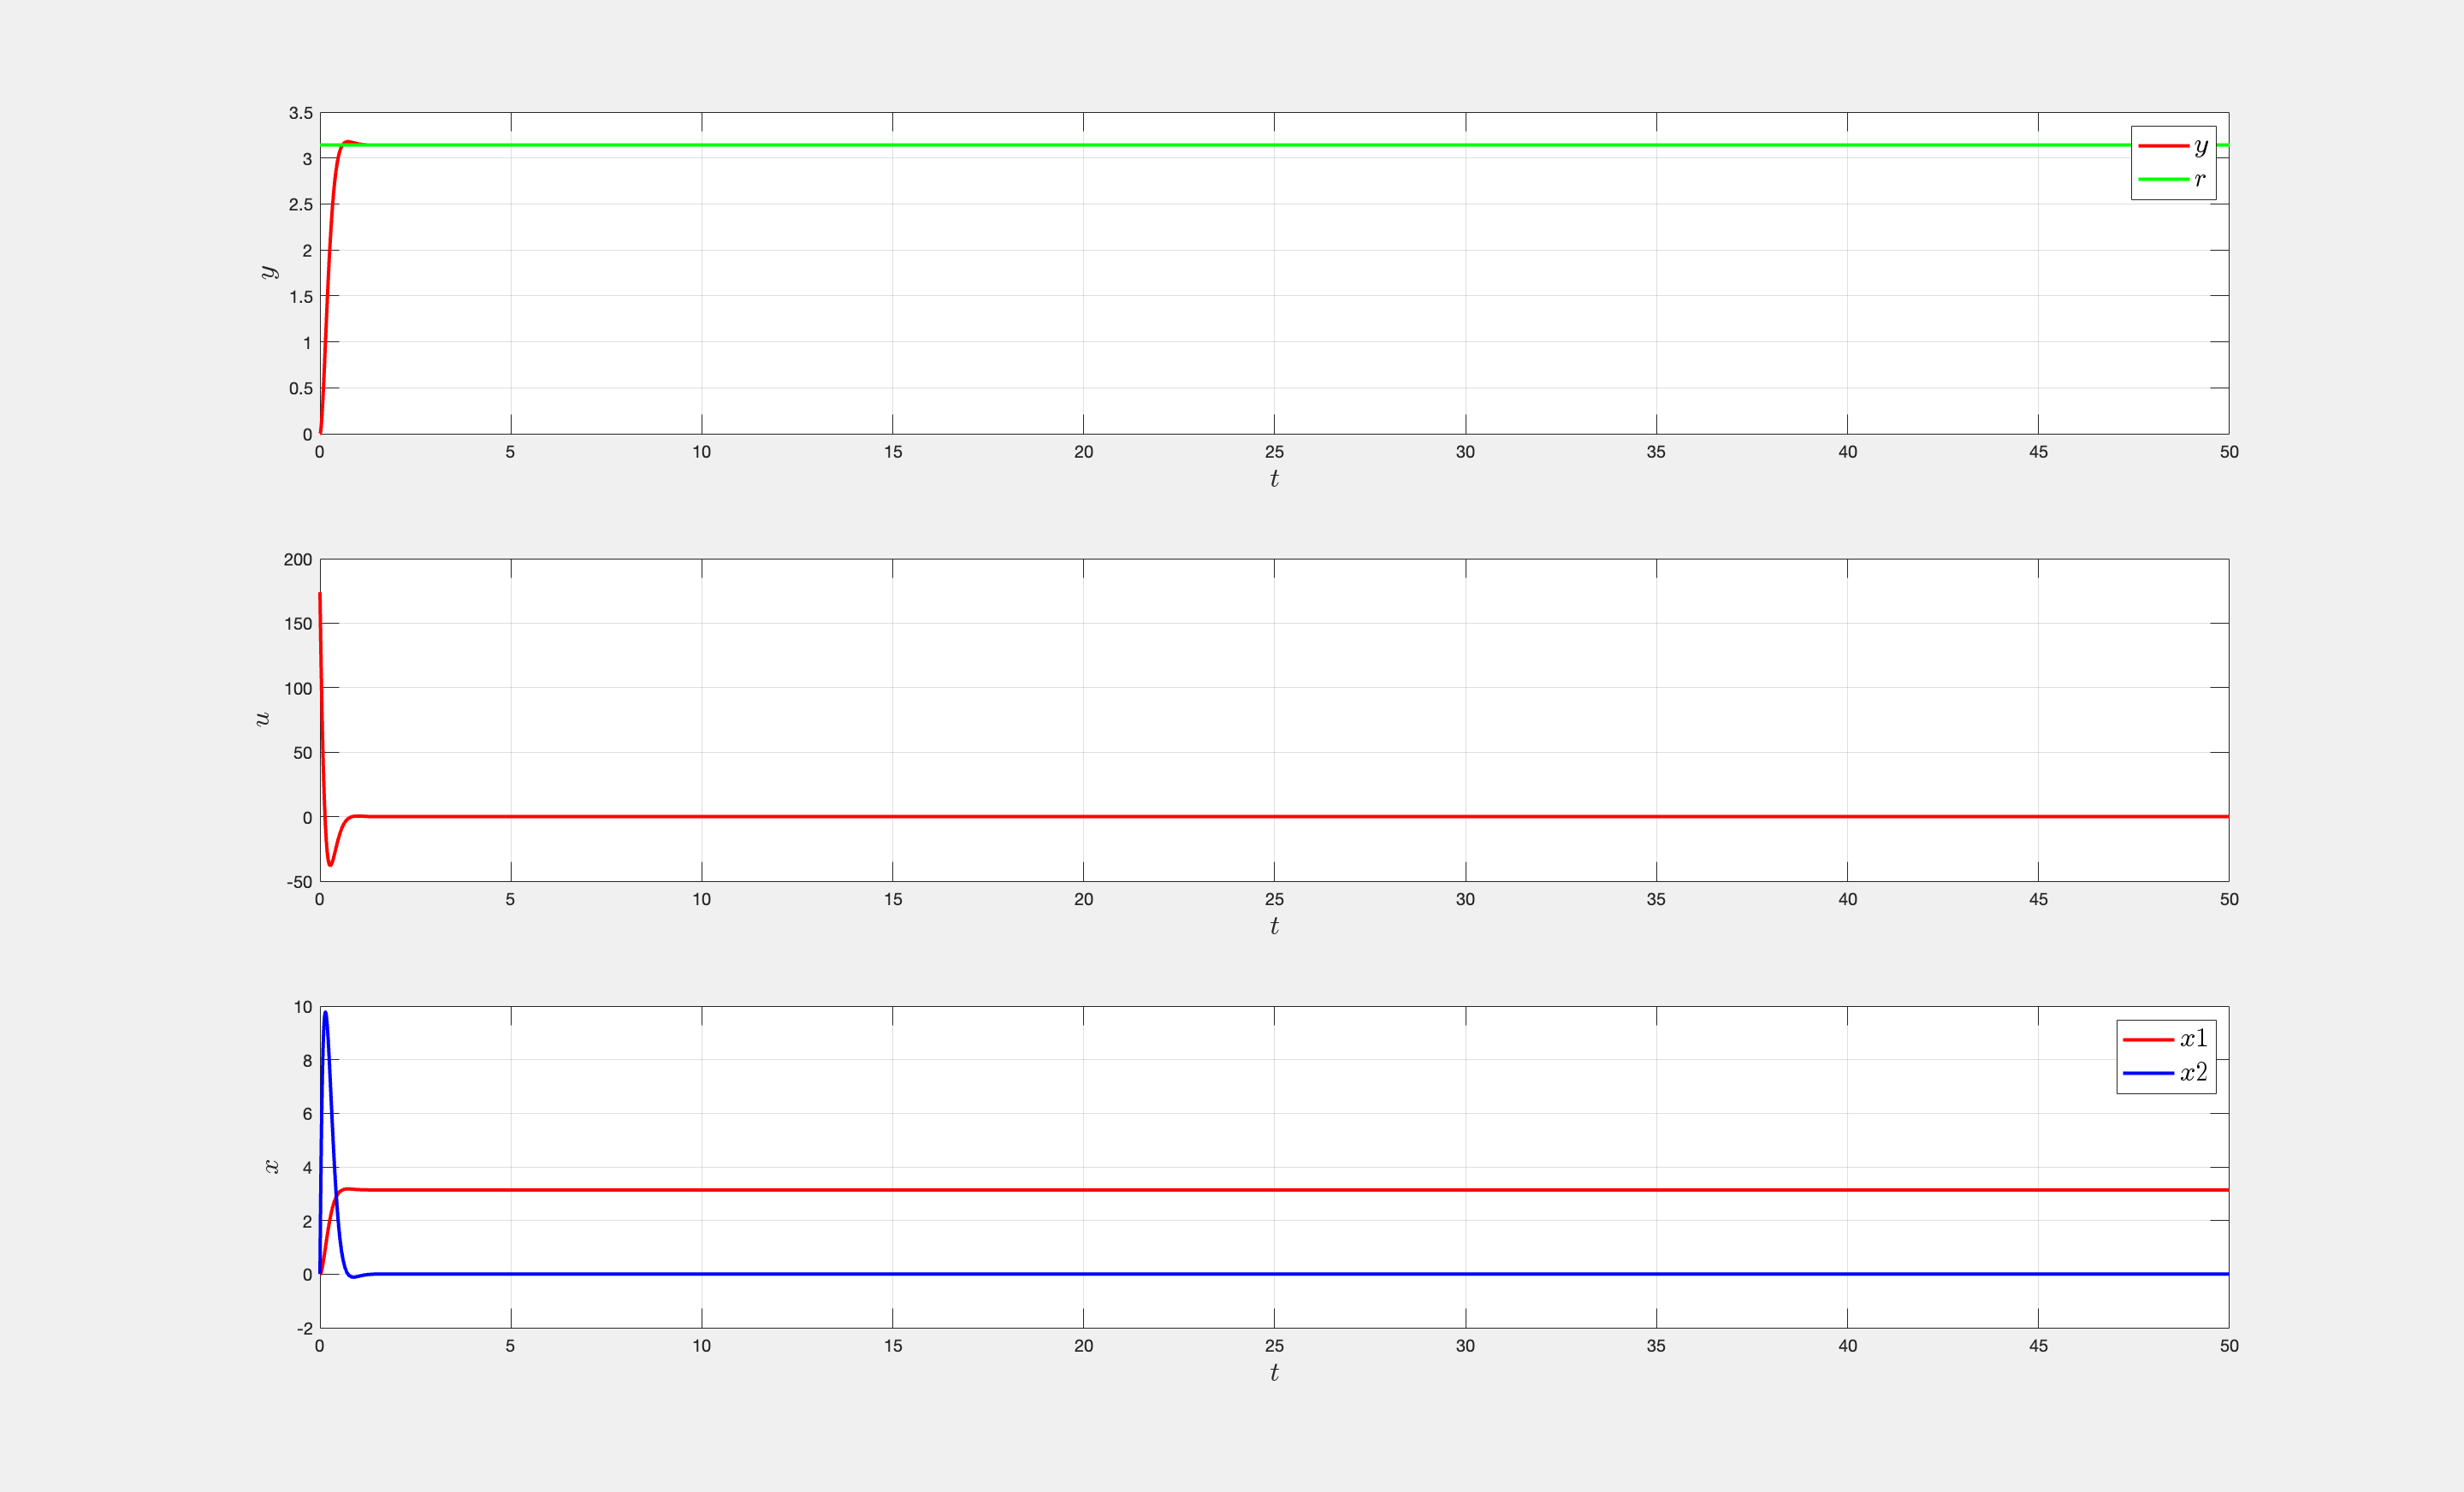

lookuptable_model = 'GainSchedulingSimulinkLookUpTable.slx';
open_system(lookuptable_model);
data = sim(lookuptable_model, 50);
%plot_data(data, "GainSchedulingSimulinkLookUpTable");
%saveas(gcf,'Risultati_Gain_LookUpTable/Results.png');
% Genera un timestamp unico per includere nella stringa del nome del file
timestamp = datestr(now, 'yyyymmdd_HHMMSS');

% Crea una stringa univoca per il nome del file
imageName = ['Results_', timestamp, '.png'];

% Plot dei dati
plot_data(data, "GainSchedulingSimulinkLookUpTable");

% Salva l'immagine con un nome univoco
saveas(gcf, fullfile('Risultati_Gain_LookUpTable', imageName))

#### Analisi

y = squeeze(data.y.Data); % Ridimensiona y per rimuovere le dimensioni singolari
t = squeeze(data.t.Data); % Ridimensiona y per rimuovere le dimensioni singolari
results=stepinfo(y,t);
disp('Step Information for the Output');

Step Information for the Output


disp(results);

         RiseTime: 0.3412
    TransientTime: 0.5232
     SettlingTime: 0.5232
      SettlingMin: 2.8653
      SettlingMax: 3.1779
        Overshoot: 1.1570
       Undershoot: 0
             Peak: 3.1779
         PeakTime: 0.7580

